## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Filtering**

## **Lab Session 2**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **(Dúvidas: filtro passa-baixo e equalizer)**

**%%REMINDER: enviar projeto com source files na pasta zipada**

# **I) 1D Filtering**

**1) ** *y = filtro(x, A, B)**** definida no ficheiro filtro.m****. *Read the file "filtro.m". Explain how it works. 

- Ao atuar num *vetor de input x*, a função *y = filtro(x, A, B)* tem como *output um vetor y*. Os coeficientes contidos em A e em B definem as características do filtro.

- Cada elemento de ***A(i)***, que são coeficientes, vai multiplicar pelo elemento do ***vetor x*** na posição ***n-i***, sendo ***n*** a entrada atual que se está a calcular no ***vetor y***. A isto, soma-se adicionalmente cada elemento de ***B(j)*** a multiplicar pelo elemento do ***vetor y*** na posição ***n-j***. Portanto, é necessário "saber" saídas "passadas". Obtém-se assim todas as entradas do*** vetor y***.

**2) ** Generate a square wave of *T = 10* s with a period of *Tp = 1* s and *fs* = *50 Hz*. Filter the signal with different coefficients.

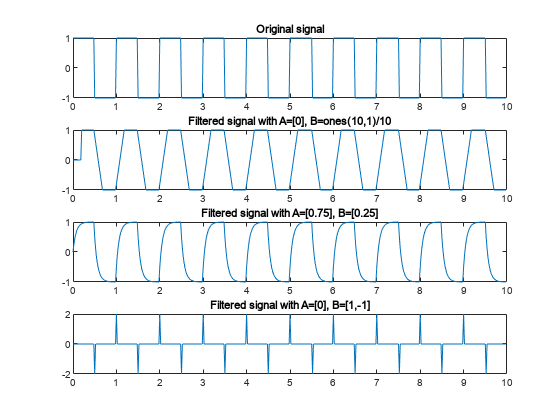

% Generate square wave
T = 10; % Total time
Tp = 1; % Period
fs = 50; % Sampling frequency
t = 0:1/fs:T-1/fs; % Time vector, 10-1/50 para ir até t=10s tops
x = square(2*pi*t/Tp); % Square wave signal

% a) Filter the signal with coefficients A = [0], B = ones(10, 1)/10
A = 0;
B = ones(10, 1)/10;
y1 = filtro(x', A, B); % Filtered signal

% b) Filter with coefficients A = [0.75], B = [0.25]
A = 0.75;
B = 0.25;
y2 = filtro(x', A, B); % Filtered signal

% c) Filter with coefficients A = [0], B = [1, -1]
A = 0;
B = [1, -1];
y3 = filtro(x', A, B'); % Filtered signal

% Plot results
figure;
subplot(4,1,1);
plot(t, x);
title('Original signal');
subplot(4,1,2);
plot(t, y1);
title('Filtered signal with A=[0], B=ones(10,1)/10');
subplot(4,1,3);
plot(t, y2);
title('Filtered signal with A=[0.75], B=[0.25]');
subplot(4,1,4);
plot(t, y3);
title('Filtered signal with A=[0], B=[1,-1]');

# **comentar**

**3) **For audio files "fungeesAWGN.wav" corrupted by AWGN and "fuggesSaltPeper.wav" corrupted by SPN, make the following:

**a)** Read the audio file, listen to it and represent it graphically. **Can you identify, in the plot, the noise corrupting the music?**

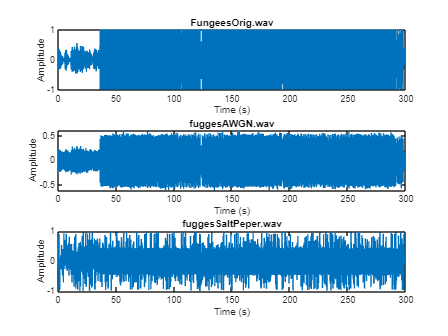

% Read the audio files
[x_awgn, fs_awgn] = audioread('fuggesAWGN.mp3');
[x_spn, fs_spn] = audioread('fuggesSaltPeper.mp3');
[x_orig, fs_orig] = audioread('FugeesOrig.mp3');

%Listen to the audiofiles
%sound(x_awgn, fs_awgn);
%sound(x_spn, fs_spn);
%sound(x_orig, fs_orig);

% Plot the audio signals
t_awgn = (0:length(x_awgn)-1)/fs_awgn;
t_spn = (0:length(x_spn)-1)/fs_spn;
t_orig = (0:length(x_orig)-1)/fs_orig;

%Plot
figure;
subplot(3,1,1);
plot(t_orig, x_orig);
title('FungeesOrig.wav');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,2);
plot(t_awgn, x_awgn);
title('fuggesAWGN.wav');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,3);
plot(t_spn, x_spn);
title('fuggesSaltPeper.wav');
xlabel('Time (s)');
ylabel('Amplitude');

**b)** Use the routine implemented in question *1)* to filter the signal with a linear low-pass filter with the following coefficients A = [0.75], B = [0.25]. Comment the results, namely concerning the quality of the audio output signal.

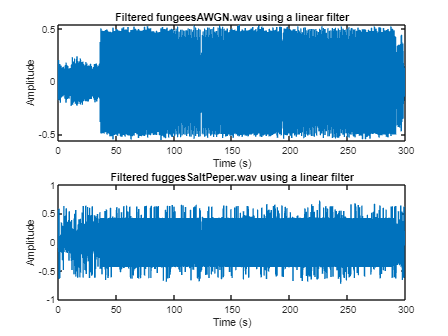

% Filter the audio signals using the linear low-pass filter
A = 0.75;
B = 0.25;
y_awgn = filtro(x_awgn', A, B);
y_spn = filtro(x_spn', A, B);

% Play and plot the filtered audio signals
%sound(y_awgn, fs_awgn);
%sound(y_spn, fs_spn);

%Plot
figure;
subplot(2,1,1);
plot(t_awgn, y_awgn);
title('Filtered fungeesAWGN.wav using a linear filter');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2,1,2);
plot(t_spn, y_spn);
title('Filtered fuggesSaltPeper.wav using a linear filter');
xlabel('Time (s)');
ylabel('Amplitude');

- Os sinais de áudio resultantes da filtragem exibem uma redução no ruído, especialmente no caso do sinal anteriormente corrompido pelo SPN. No entanto, os sinais de saída ainda exibem alguns artefatos devido à resposta não ideal do filtro.

**c)** Filter now the audio signal with the median filter. Listen the result and compare it with the one obtained with the linear filter.

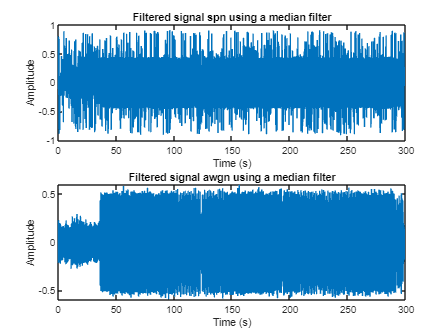

% Filter the signal using the median filter
N = 3;
y_med_awgn = medfilt1(x_awgn, N);
y_med_spn = medfilt1(x_spn, N);

% Play the filtered signal
%sound(y_med_awgn, fs_awgn);
%sound(y_med_spn, fs_spn);

% Plot the waveform of the filtered signal
figure;
subplot(2,1,1);
plot(t_spn, y_med_spn);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered signal spn using a median filter');
subplot(2,1,2);
plot(t_awgn, y_med_awgn);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered signal awgn using a median filter');

- Comparando os resultados do filtro passa-baixo linear e do filtro mediana, podemos observar que o filtro mediana preserva melhor os transientes agudos do sinal do que o filtro linear, mas também introduz alguma distorção no sinal. No entanto, o filtro linear remove o ruído de alta frequência de forma mais eficaz e produz um sinal de saída mais suave.

**d) **Em relação aos resultados obtidos com a filtragem dos sinais de áudio com o filtro linear passa-baixo e o filtro mediano, podemos fazer os seguintes comentários:

- O sinal de áudio filtrado usando o filtro passa-baixo linear é mais suave e reduz o ruído de alta frequência em comparação com o sinal original. O filtro passa-baixo atenua os componentes de alta frequência do sinal, que normalmente estão associados ao ruído, e passa os componentes de baixa frequência do sinal. Como resultado, o sinal de áudio filtrado é mais limpo e agradável de ouvir. No entanto, o filtro também suaviza algumas das características transitórias do sinal, que podem ser indesejáveis se forem importantes para a percepção ou análise da música;

- O sinal de áudio filtrado usando o filtro mediana preservou os transientes agudos do sinal melhor do que o filtro linear, mas também introduziu alguma distorção no sinal. O filtro mediana substitui cada amostra no sinal pela mediana de suas amostras vizinhas, o que pode efetivamente remover os picos ou impulsos no sinal causados pelo ruído. No entanto, o filtro também produz alguma distorção no sinal porque é não linear e modifica a forma da forma de onda. A distorção pode ser audível e afetar a qualidade da música.

- No geral, a escolha do filtro depende dos requisitos específicos da aplicação e do compromisso entre redução de ruído e distorção do sinal. Se preservar as características transitórias do sinal for importante, o filtro mediano pode ser o preferido. Se reduzir o ruído e suavizar o sinal for a prioridade, o filtro passa-baixo linear pode ser mais adequado.

# **II) 2D FILTERING**

**1) ** Load the image "len_gray.jpg" and corrupt it with salt and pepper noise. Visualize the noisy image with the imagesc and mesh functions. Comment. 

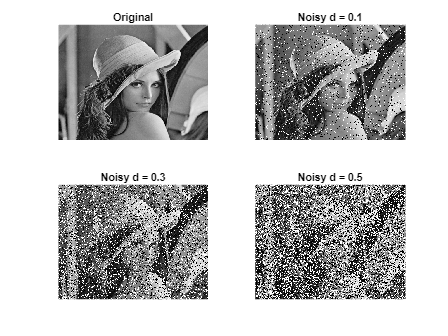

% Imagem Original
x = double(imread('len_gray.jpg'));
x = (x-min(x(:)))/(max(x(:))-min(x(:)));
% Imagem Noisy with salt & papper with noise density d = 0.1
y_1 = imnoise(x,'salt & pepper', 0.1);
% Imagem Noisy with salt & papper with noise density d = 0.3
y_2 = imnoise(x,'salt & pepper', 0.3);
% Imagem Noisy with salt & papper with noise density d = 0.5
y_3 = imnoise(x,'salt & pepper', 0.5);

%Plot results
figure;
colormap(gray(256));
subplot(2,2,1); imagesc(x);
axis off; title('Original');
subplot(2,2,2); imagesc(y_1);
axis off; title('Noisy d = 0.1');
subplot(2,2,3); imagesc(y_2);
axis off; title('Noisy d = 0.3');
subplot(2,2,4); imagesc(y_3);
axis off; title('Noisy d = 0.5');

- Salt and pepper noise manifests itself with the insurgency of random black and white pixels. We changed the amount of noise with *d*, being *d = 0.05* correspondent to 5% of the total number of pixels of the image being affected by this effect. As we can see, the higher is *d*, the less understandable and the more deteriorated is the final result.

- We'll use the corrupted picture with *d = 0.3* from now on.

**2) ** Filter the original image "len gray.jpg" with the following masks. Comment. 

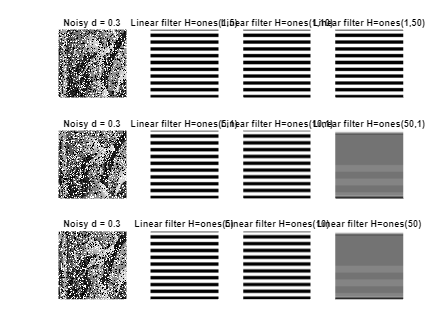

% Values of N
N1 = 5;
N2 = 10;
N3 = 50;

% a) Linear filtering using H = ones(1, N)
ya_N0 = conv2(y2, ones(1,N1),'same');
ya_N1 = conv2(y2, ones(1,N1),'same');
ya_N2 = conv2(y2, ones(1,N2),'same');
ya_N3 = conv2(y2, ones(1,N3),'same');

% b) Linear filtering using H = ones(N, 1)
yb_N1 = conv2(y2, ones(N1,1),'same');
yb_N2 = conv2(y2, ones(N2,1),'same');
yb_N3 = conv2(y2, ones(N3,1),'same');

% c) Linear filtering using H = ones(N)
yc_N1 = conv2(y2, ones(N1),'same');
yc_N2 = conv2(y2, ones(N2),'same');
yc_N3 = conv2(y2, ones(N3),'same');

%Plot results
figure;
colormap(gray(256));
subplot(3,4,1); imagesc(y_2);
axis off; title('Noisy d = 0.3');
subplot(3,4,2); imagesc(ya_N1);
axis off; title('Linear filter H=ones(1,5)');
subplot(3,4,3); imagesc(ya_N2);
axis off; title('Linear filter H=ones(1,10)');
subplot(3,4,4); imagesc(ya_N3);
axis off; title('Linear filter H=ones(1,50)');
subplot(3,4,5); imagesc(y_2);
axis off; title('Noisy d = 0.3');
subplot(3,4,6); imagesc(yb_N1);
axis off; title('Linear filter H=ones(5,1)');
subplot(3,4,7); imagesc(yb_N2);
axis off; title('Linear filter H=ones(10,1)');
subplot(3,4,8); imagesc(yb_N3);
axis off; title('Linear filter H=ones(50,1)');
subplot(3,4,9); imagesc(y_2);
axis off; title('Noisy d = 0.3');
subplot(3,4,10); imagesc(yc_N1);
axis off; title('Linear filter H=ones(5)');
subplot(3,4,11); imagesc(yc_N2);
axis off; title('Linear filter H=ones(10)');
subplot(3,4,12); imagesc(yc_N3);
axis off; title('Linear filter H=ones(50)');

# **comentar**

- A partir desta etapa, utilizamos a imagem com densidade de ruído d = 0.3 para efeitos de filtragem.

**3)**  Filter the image with a Gaussian mask for different values of the parameters of the window. Comment the result with respect to the effectiveness of noise removal.

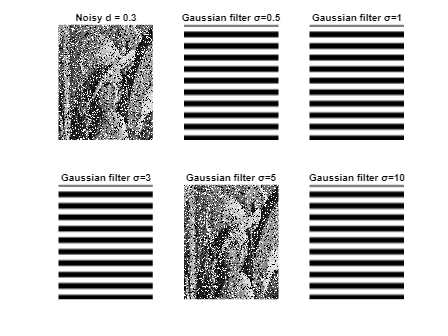

% Use the window function to generate a Gaussian mask
% sigma = (L – 1)/(2*alpha)
w1 = gausswin(2,1); % sigma = 0.5
w2 = gausswin(3,1); % sigma = 1
w3 = gausswin(5,1); % sigma = 2
w4 = gausswin(11,1); % sigma = 5
w5 = gausswin(21,1); % sigma = 10
 
% Gaussian filtering
y_g1 = conv2(y2,w1,'same');
y_g2 = conv2(y2,w2,'same');
y_g3 = conv2(y2,w3,'same');
y_g4 = conv2(y2,w4,'same');
y_g5 = conv2(y2,w5,'same');

%Plot results
figure;
colormap(gray(256));
subplot(2,3,1); imagesc(y_2);
axis off; title('Noisy d = 0.3');
subplot(2,3,2); imagesc(ya_N1);
axis off; title('Gaussian filter σ=0.5');
subplot(2,3,3); imagesc(ya_N2);
axis off; title('Gaussian filter σ=1');
subplot(2,3,4); imagesc(ya_N3);
axis off; title('Gaussian filter σ=3');
subplot(2,3,5); imagesc(y_2);
axis off; title('Gaussian filter σ=5');
subplot(2,3,6); imagesc(yb_N1);
axis off; title('Gaussian filter σ=10');

# **comentar**

**4) **Filter the image using a 2D median filter and compare the results with the one obtained in the previous item. Test with several values of the parameters. Comment.

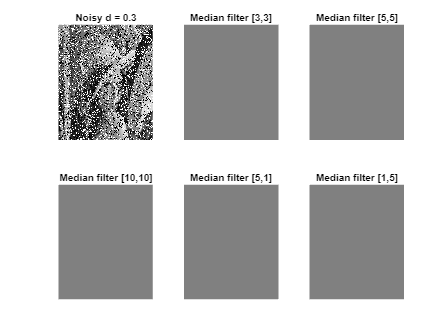

% Filtered with median filter
y_med1 = medfilt2(y2); % [m,n] = 3,3 by default
y_med2 = medfilt2(y2,[5,5]);
y_med3 = medfilt2(y2,[10,10]);
y_med4 = medfilt2(y2,[5,1]);
y_med5 = medfilt2(y2,[1,5]);

% Plot results
figure;
colormap(gray(256));
subplot(2,3,1); imagesc(y_2);
axis off; title('Noisy d = 0.3');
subplot(2,3,2); imagesc(y_med1);
axis off; title('Median filter [3,3]');
subplot(2,3,3); imagesc(y_med1);
axis off; title('Median filter [5,5]');
subplot(2,3,4); imagesc(y_med1);
axis off; title('Median filter [10,10]');
subplot(2,3,5); imagesc(y_med1);
axis off; title('Median filter [5,1]');
subplot(2,3,6); imagesc(y_med1);
axis off; title('Median filter [1,5]');

**5)** Convolve the original image "len gray.jpg" with the given 2D masks

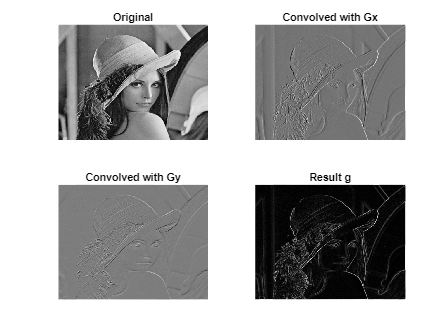

% Define 2D masks
Gx = [-1,0,1; -2,0,2; -1,0,1];
Gy = [1,2,1; 0,0,0; -1,-2,-1];

% Convolve the original image
y_Gx = conv2(x,Gx,'same');
y_Gy = conv2(x,Gy,'same');

% Compute image g
g = sqrt(y_Gx.^2 + y_Gy.^2);
gmin = min(min(g));
range = max(max(g)) - gmin; % find range
g = floor((g-gmin)/range*255); % normalise from 0 to 255

% Visualize results
figure;
colormap(gray(256));
subplot(2,2,1); imagesc(x);
axis off; title('Original');
subplot(2,2,2); imagesc(y_Gx);
axis off; title('Convolved with Gx');
subplot(2,2,3); imagesc(y_Gy);
axis off; title('Convolved with Gy');
subplot(2,2,4); imagesc(g);
axis off; title('Result g');

**6) **The previous filter is called Sobel operator. What type is this filter? Why? Comment?

- The Sobel filter is a derivative filter and it allows to determine the edges in an image. It is based in gradient, so it looks for changes in the first derivative of the image. It uses a pair of two 3x3 masks, in this case Gx and Gy, which estimate the gradient in the x and the y direction, respectively. So, it detects horizontal and vertical "edges" separately.

**7) **Use the MatLab function edge with parameters ’sobel’ and ’canny’ with the same image. Comment and compare the results and correlate them with the ones obtained in the 4) and 6).

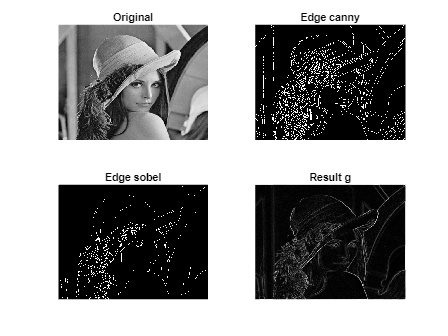

% Use the edge function with the same image
y_canny = edge(x,'Canny');
y_sobel = edge(x,'Sobel');

% Visualize results
figure;
colormap(gray(256));
subplot(2,2,1); imagesc(x);
axis off; title('Original');
subplot(2,2,2); imagesc(y_canny);
axis off; title('Edge canny');
subplot(2,2,3); imagesc(y_sobel);
axis off; title('Edge sobel');
subplot(2,2,4); imagesc(g);
axis off; title('Result g');

# comment